## Fit medium voxel with GLM model

sub_name = 'HERO_JM';
acq_base = 'NeuralCoding%02d';

nRuns = 1;
acq_idx = {1:nRuns};
base_idx = 0;
modelClass = 'glm';

% Setup the structure of a single acquisition
expPara = struct('acqLen', 320, 'nStim', 39, ...
    'stimDur', 1.5, 'stimDly', 6.0, 'blankDur', 13.75);

% Session: NeuralCoding00
idx = 1;
ses_idx = 0;

acq_type = sprintf(acq_base, ses_idx);
fprintf('Run %s fitting for %s \n', modelClass, acq_type);

Run glm fitting for NeuralCoding00 


% load data defined by ROI
data = load_session(sub_name, acq_type, acq_idx{idx}, false);
[roi_mask, v_label, e_label] = define_roi(sub_name);

V1 V2 V3 # of Voxel: 3479 
Eccen mask: 2125 / 3479 selected 
Rsqur mask: 1967 / 2125 selected 



% median voxel
data = data(roi_mask, :);
medianTS = median(data, 1);

% Run GLM model fit
results = glm_fit(medianTS, expPara, [], base_idx(idx), ...
    'showPlot', false, 'modelClass', modelClass);

Constglm:  000%  |                                          | 0/1it [00:glm:  000%  |                                          | 0/1it [00:00:00<Inf:NaN:NaN, Inf s/it]
Elapsed time is 0.183540 seconds.



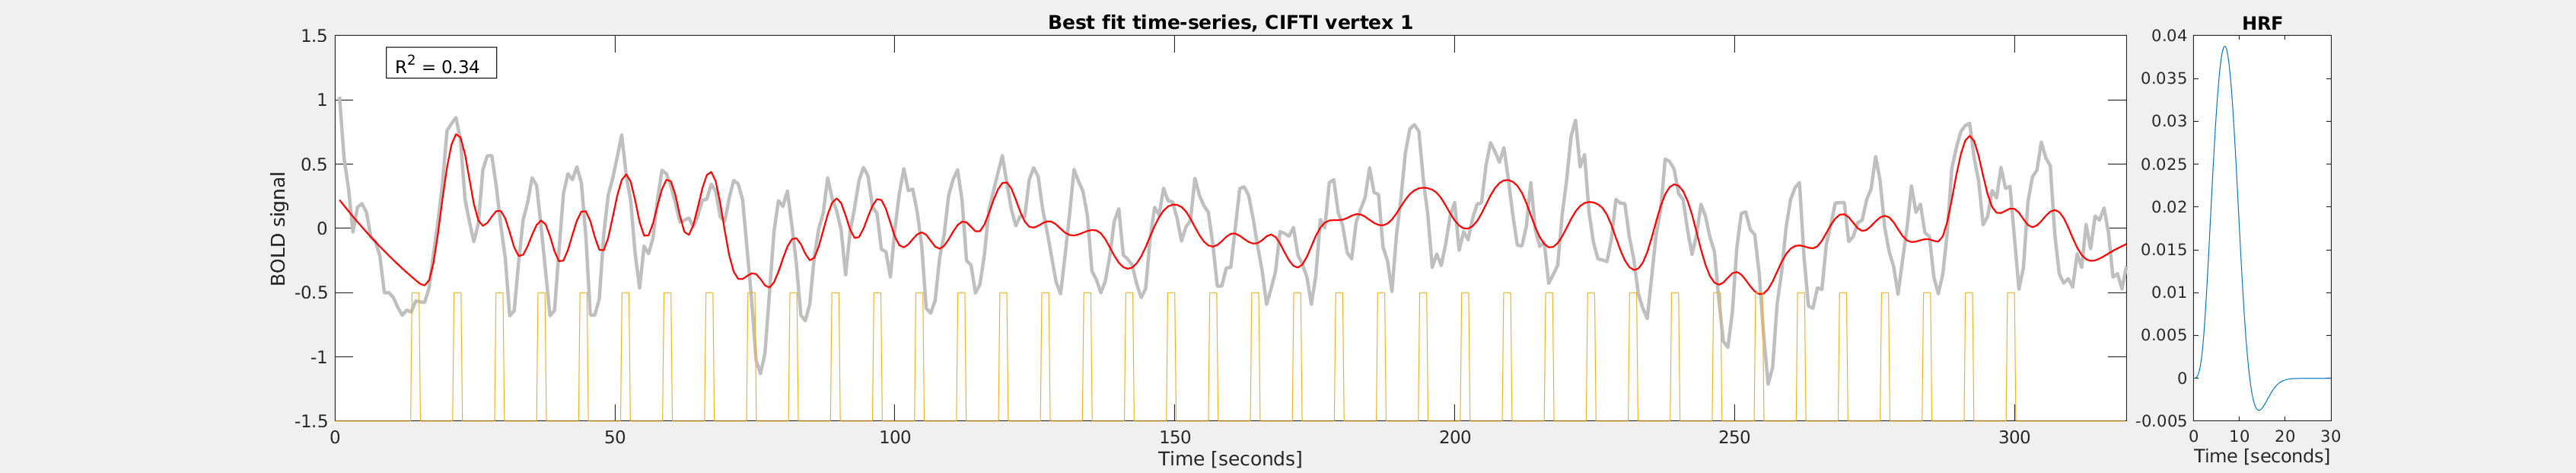

stim = sum(results.stim, 1);

% add the varea label and eccentricity label to results struct
results.v_label = v_label;
results.e_label = e_label;

% Show the results figures
figFields = fieldnames(results.figures);
if ~isempty(figFields)
    for ii = 1:length(figFields)
        figHandle = struct2handle(results.figures.(figFields{ii}).hgS_070000,0,'convert');
        set(figHandle,'visible','on')
    end
    
    subplot(1, 10, 1:9);
    hold on;
    plot(results.stimTime, stim - 1.5);
    xlim([0, nRuns * 320.0]);
    ylim([-1.5, 1.5]);
end

## Fit medium voxel with mt Sinai model

modelClass = 'mtSinai';
acq_type = sprintf(acq_base, ses_idx);
fprintf('Run %s fitting for %s \n', modelClass, acq_type);

Run mtSinai fitting for NeuralCoding00 


% load data defined by ROI
data = load_session(sub_name, acq_type, acq_idx{idx}, false);
[roi_mask, v_label, e_label] = define_roi(sub_name);

V1 V2 V3 # of Voxel: 3479 
Eccen mask: 2125 / 3479 selected 
Rsqur mask: 1967 / 2125 selected 


ConstrmtSinai:  000%  |                                          | 0/1it [00:00:00<Inf:NaN:NaN, Inf s/it]


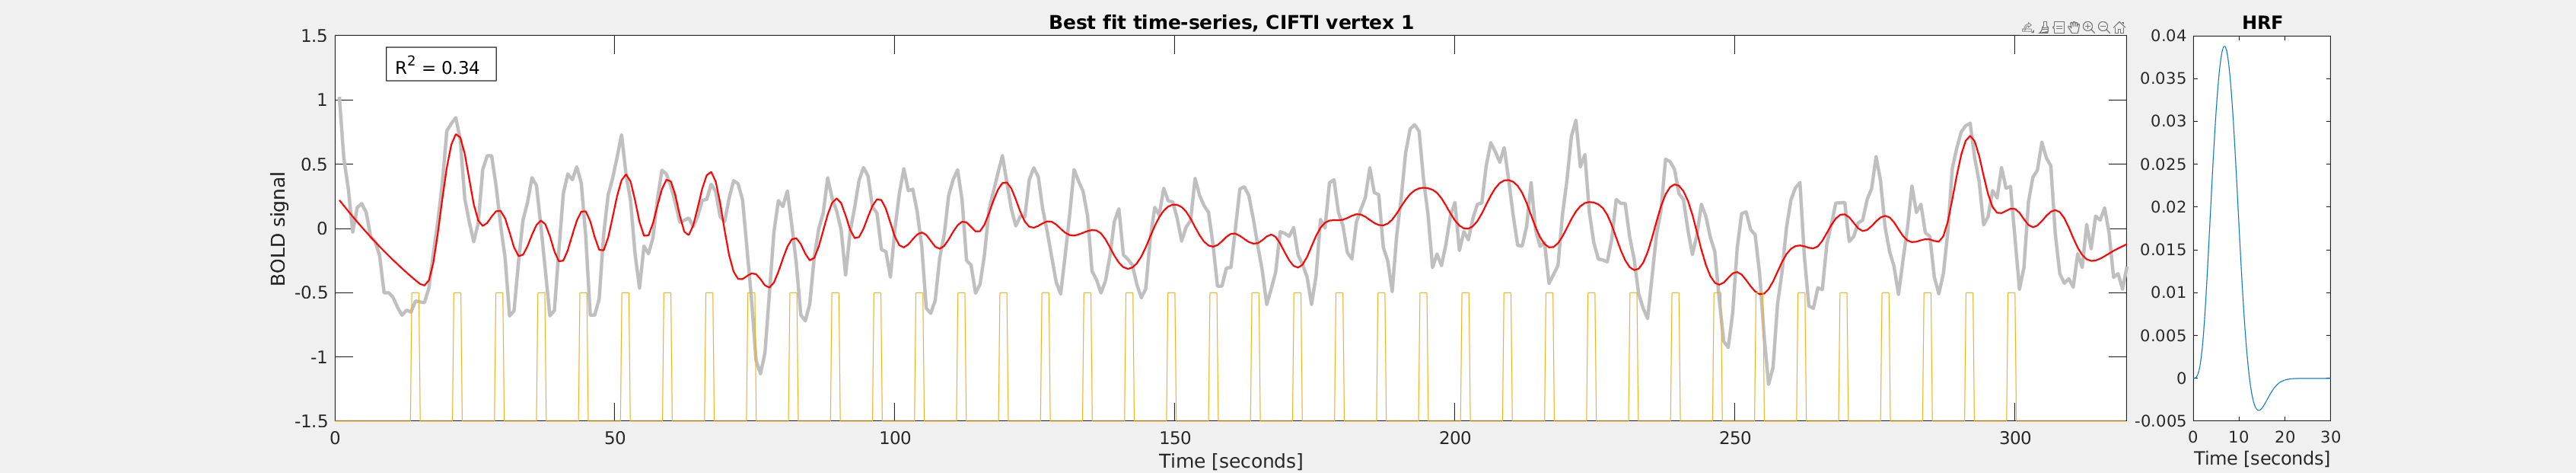

Elapsed time is 0.532266 seconds.



% median voxel
data = data(roi_mask, :);
medianTS = median(data, 1);

% Run GLM model fit
results = glm_fit(medianTS, expPara, [], base_idx(idx), ...
    'showPlot', false, 'modelClass', modelClass);

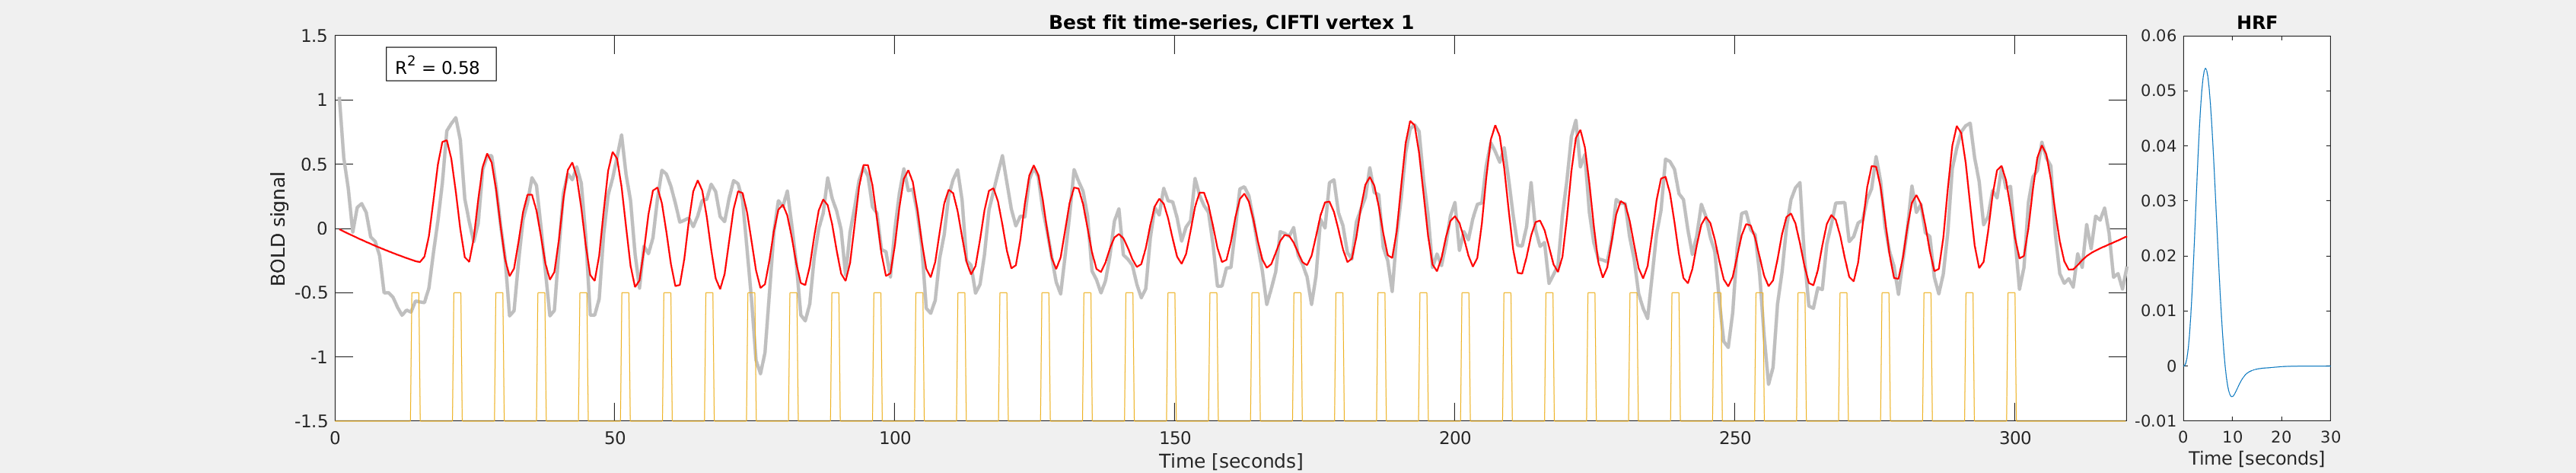

stim = sum(results.stim, 1);

% add the varea label and eccentricity label to results struct
results.v_label = v_label;
results.e_label = e_label;

% Show the results figures
figFields = fieldnames(results.figures);
if ~isempty(figFields)
    for ii = 1:length(figFields)
        figHandle = struct2handle(results.figures.(figFields{ii}).hgS_070000,0,'convert');
        set(figHandle,'visible','on')
    end
    
    subplot(1, 10, 1:9);
    hold on;
    plot(results.stimTime, stim - 1.5);
    xlim([0, nRuns * 320.0]);
    ylim([-1.5, 1.5]);
end